# Lesson 1: Visualize the dataset

Your simulator have generated `phase` and `amp` matrices, using the `patt` (for pattern) images.

You load the data into the workspace:

load('lesson1.mat');
whos -file lesson1.mat

  Name              Size                       Bytes  Class     Attributes

  amp              61x1x1875                  915000  double              
  geom            263x263x1875            1037535000  double              
  phase            61x1x1875                  915000  double              
  wavelength        1x61                         488  double              



#### Task 1. Visualize random images on a plot in an array of NxN subplots.

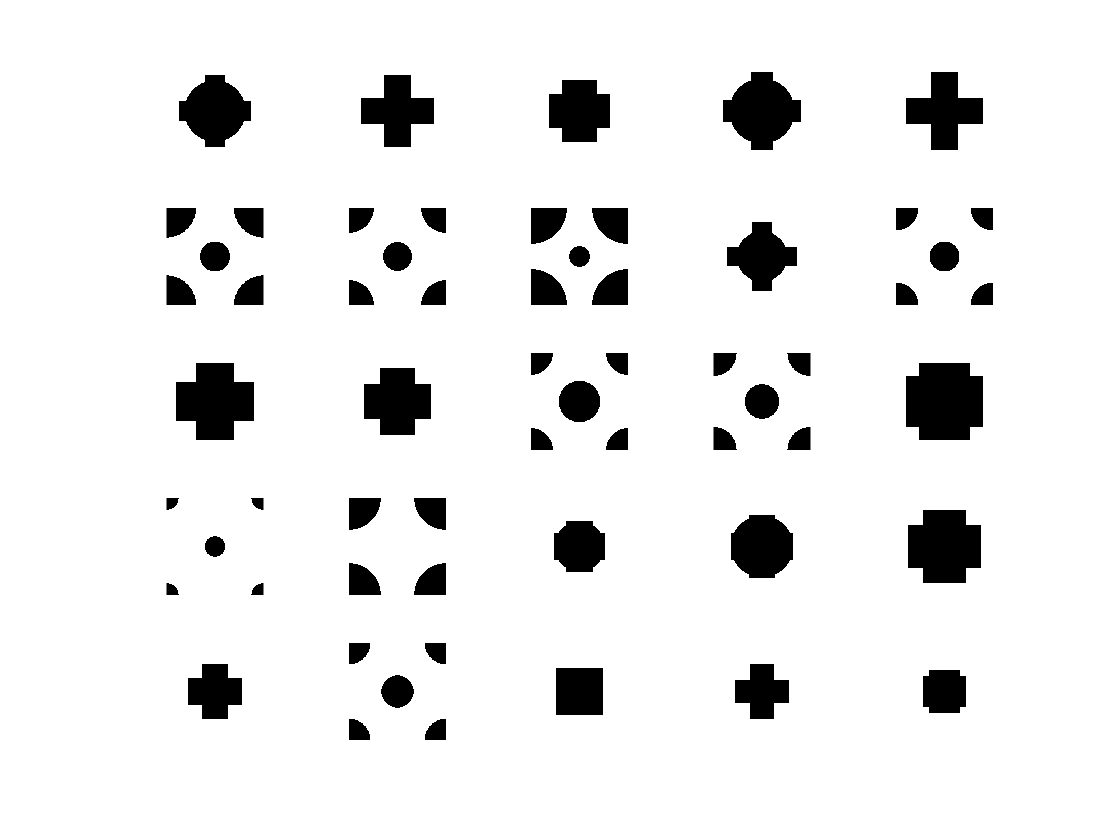

% Hint: use subplot in a loop, pcolor or imshow for displaying
N = 5;
x = randi(size(geom,3),[1 N^2]);
figure
for i = 1:N^2
    subplot(N,N,i)
    imshow(geom(:,:,x(i))); 
end

#### Task 2. Obtaian $\Delta\varphi$ and $\varphi_0$ as difference on the edges and central phase and use average efficiency as the color.

[~, mid] = min(abs(wavelength - mean(wavelength)));
phi0 = squeeze(phase(mid,:,:));
delta_phi = squeeze(diff(phase([end 1],:,:)));
ave = squeeze(mean(amp.^2));

#### Task 3. Make a scatter plot of $\varphi_0$ vs $\Delta\varphi$. 

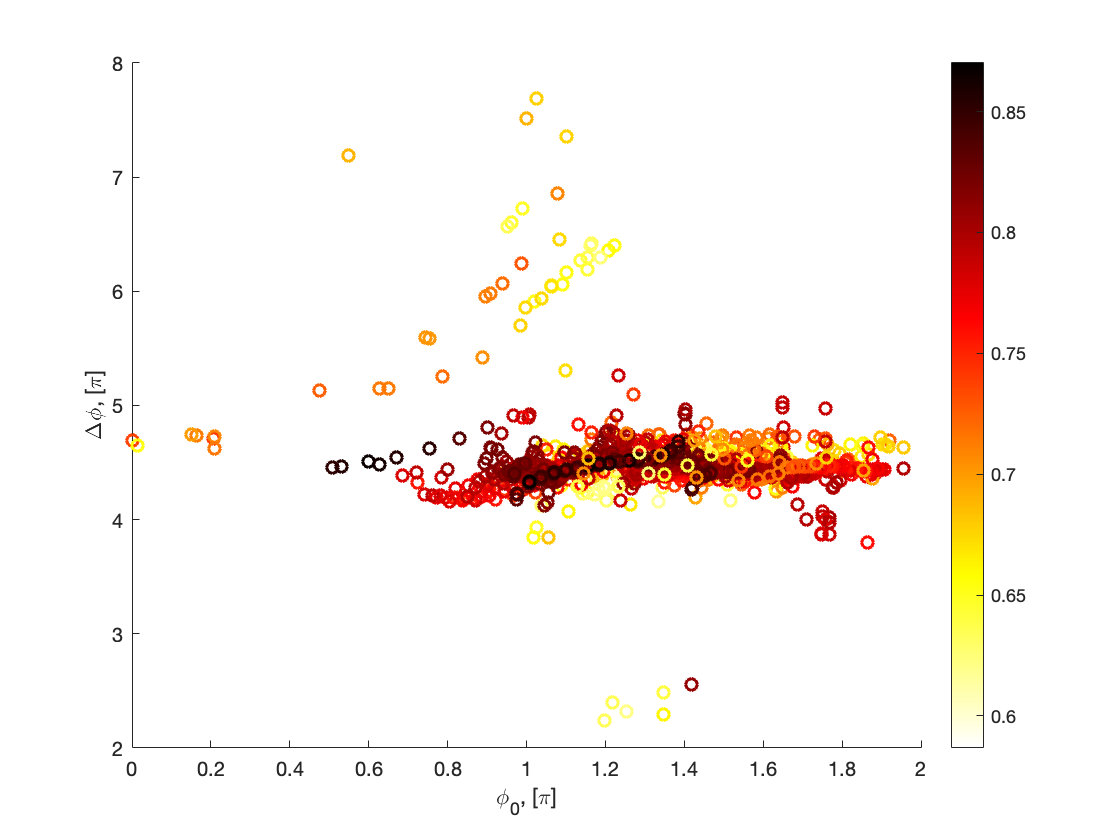

figure; scatter(phi0/pi, delta_phi/pi, 36, ave, "LineWidth", 1.5); 
colormap(flipud(hot)); colorbar
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

#### Task 4. Use MATLAB's least square approximation algorithm for getting $\Delta\varphi$ and $\varphi_0$.

[phi0_2, delta_phi_2] = deal(zeros(1,size(geom,3)));
for i = 1:size(geom,3)
    p = polyfit(wavelength(:) - wavelength(mid), phase(:, 1, i), 1);
    delta_phi_2(i) = p(1);
    phi0_2(i) = p(2);
end

#### Task 5. Make the same scatter plot as in Task 3. Compare results.

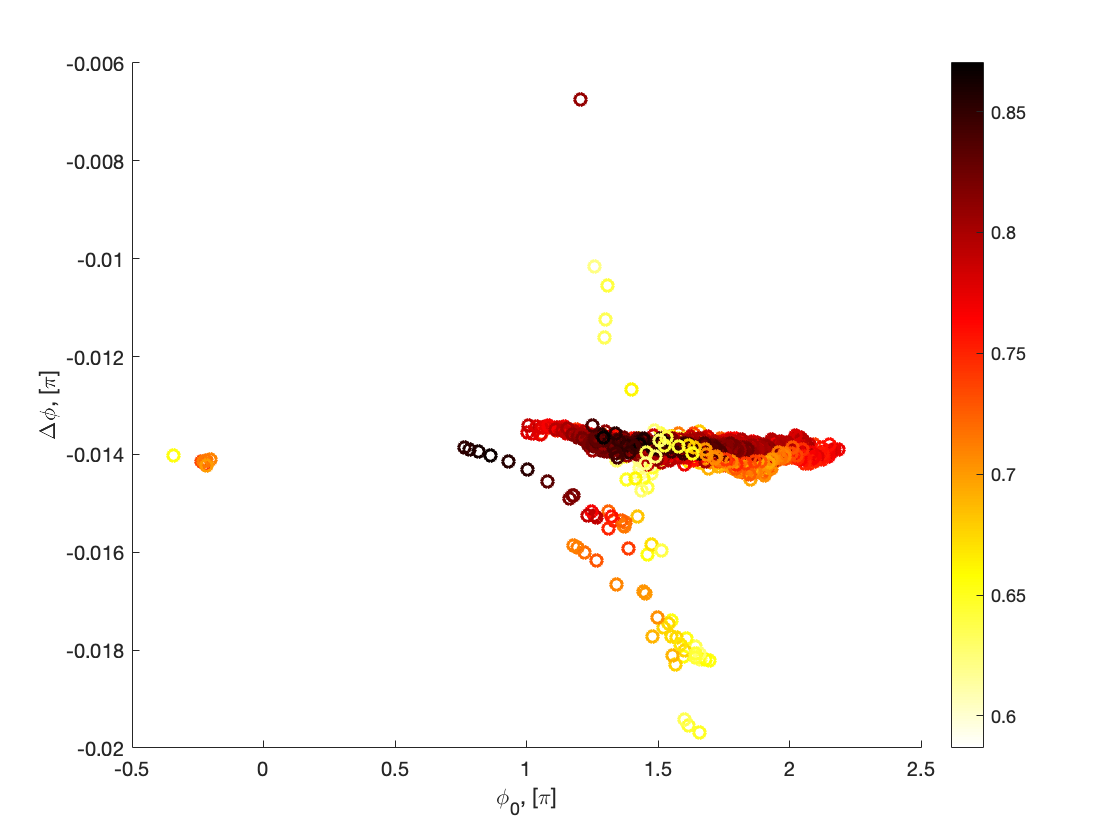

figure; scatter(phi0_2/pi, delta_phi_2/pi, 36, ave, "LineWidth", 1.5); 
colormap(flipud(hot)); colorbar
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

These two (`delta_phi` and `delta_phi_2`) have different physical dimensions. To make them the same, we have to make the following step to convert the slope [radians/length] into a phase difference [radians].

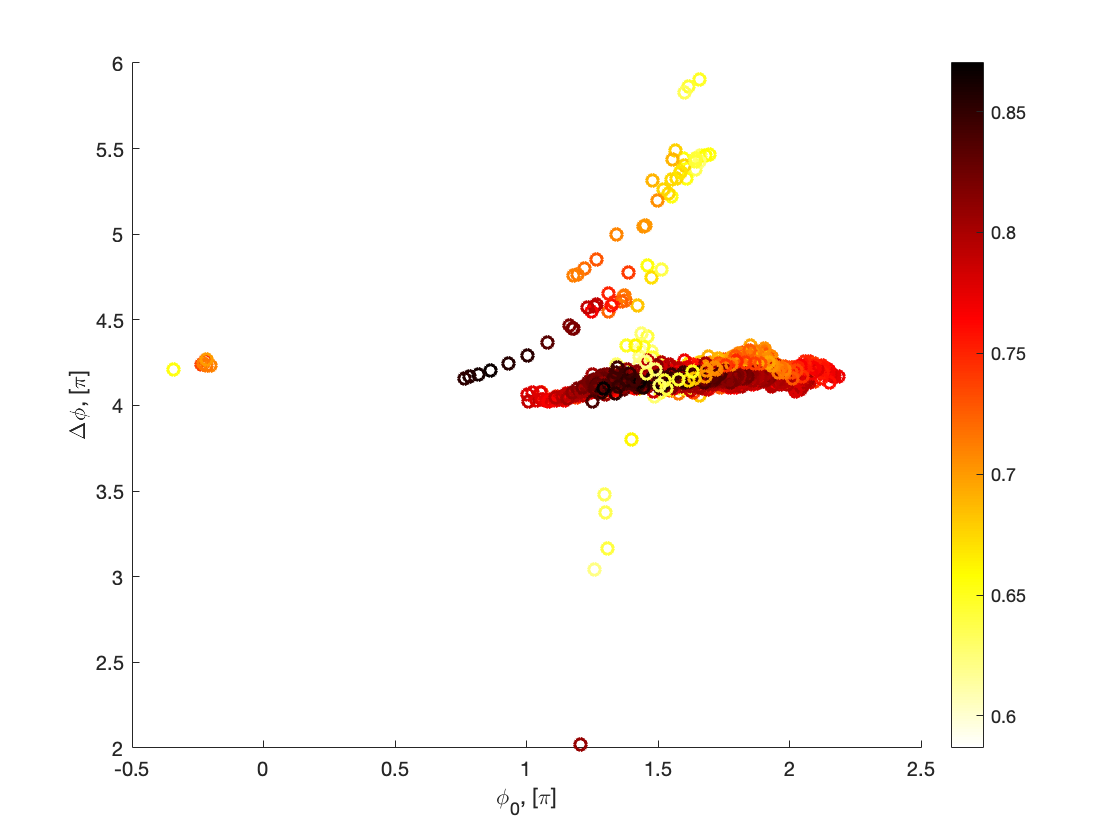

delta_phi_2 = delta_phi_2 * diff(wavelength([end 1]));
figure; scatter(phi0_2/pi, delta_phi_2/pi, 36, ave, "LineWidth", 1.5); 
colormap(flipud(hot)); colorbar
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

#### Task 6. (At home) Repeat the steps for the second order approximation.

% Hint 1: \Delta^2\phi is sum at the edges minus two central
% Hint 2: Use either different scatter plots, or a 3D one (scatter3) to
% visualize the 0, 1st and 2nd order coefficients.